# Data Pre-Processing 

## Step 1: Download Data 

Data used in this example has been provided by the [Robotics Association at Embry-Riddle](https://www.roboticsassociation.org/about-us)'s RoboSub Team. The footage contains images clicked underwater at the TRANSSDEC in San Diego, CA during practice runs at the competition. The dataset can be downloaded from a google drive here : [RoboSubFootage](https://drive.google.com/drive/folders/1bhohhPoZy03ffbM_rl8ZUPSvJ5py8rM-)

Once you have downloaded the dataset, extract the contents of the zip file and add it to the current directory. Once added to the current directory, add `RoboSubFootage` and its subfolders to the path. This should look like this:

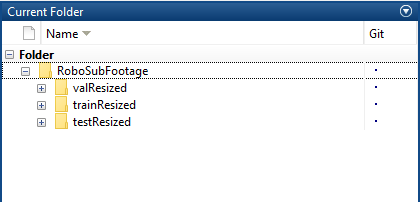

## Step 2: Image Resizing

Resize image to **416x416x3** to account for the YOLOv2 Architecture. For information on this click this [link](https://www.mathworks.com/help/vision/ug/getting-started-with-yolo-v2.html). **The dataset provided has already been resized to make it easier for sharing, this step needs to be done only if you are using your own data.** 

imageResizingNeeded = true;

if imageResizingNeeded
    folderName = "C:\Users\Owner\OneDrive\Documents\MATLAB\TribeObjectDetection\Dataset\initialimages"; % Folder with images
    
    % Create output folder
    outputFolder = fullfile(folderName, 'resized_images');
    if ~exist(outputFolder, 'dir')
        mkdir(outputFolder);
    end

    % Get all .jpg and .jpeg files
    srcFiles = [dir(fullfile(folderName, '*.jpg')); dir(fullfile(folderName, '*.jpeg'))];

    % Resize and save images
    for i = 1 : length(srcFiles)
        filename = fullfile(folderName, srcFiles(i).name);
        im = imread(filename);
        k = imresize(im, [416, 416]);

        % Save resized image in new folder
        newfilename = fullfile(outputFolder, srcFiles(i).name);
        imwrite(k, newfilename);
    end

    disp('Image resizing completed. Resized images are saved in "resized_images" folder.');
end

Error using imwrite (line 558)
Unable to open file "C:\Users\Owner\OneDrive\Documents\MATLAB\TribeObjectDetection\Dataset\initialimages\resized_images\frame_1208.jpg" for writing. Check write permission.

## Step 3: Split Folders

Split the validation dataset folder into 2, one for testing and one for validation. **The dataset provided is already split randomly using the code below, run this code if you are using your own dataset.**

splitFolder = true;


splitFolder = true;

if splitFolder
    valFolderName = "C:\Users\Owner\OneDrive\Documents\MATLAB\TribeObjectDetection\Dataset\resized_images"; % Change this to your dataset path

    % Get all image files
    files = dir(fullfile(valFolderName, '*.jpg')); % Adjust for your image format
    N = length(files);

    % Shuffle dataset
    randIdx = randperm(N); 

    % Define split sizes (adjust percentages as needed)
    trainSize = round(0.7 * N);
    valSize = round(0.2 * N);

    % Split dataset indices
    trainIdx = randIdx(1:trainSize);
    valIdx = randIdx(trainSize+1:trainSize+valSize);
    testIdx = randIdx(trainSize+valSize+1:end);

    % Create output folders
    mkdir trainResized;
    mkdir valResized;
    mkdir testResized;

    % Copy files to respective folders
    for i = 1:N
        files_re = files(i).name;
        src = fullfile(valFolderName, files_re);

        if ismember(i, trainIdx)
            dest = fullfile('trainResized', files_re);
        elseif ismember(i, valIdx)
            dest = fullfile('valResized', files_re);
        else
            dest = fullfile('testResized', files_re);
        end

        copyfile(src, dest);
    end

    disp('Dataset split completed: Train (70%), Val (20%), Test (10%)');
end

Dataset split completed: Train (70%), Val (20%), Test (10%)


## Step 4: Create Ground Truth

Use the Ground truth labeler app to label the objects of interest in the dataset. [Watch this 5-minute video to learn how to use the Ground Truth Labeler App](https://www.youtube.com/watch?v=V2e0cygY9Vg&t=16s)

isGroundTruthAvailable = false;

if isGroundTruthAvailable
    labelingSessionName = fullfile("Utilities","groundTruthLabelingSessionRoboSubResizedTrain.mat");
    groundTruthLabeler(labelingSessionName)

else
    groundTruthLabeler;
    

### Using custom automation algorithms

The built-in algoirthms in the Ground Turth Labeler app are generic feature detectors or interpolators, you can also integrate your own custom algoirthms containing detectors that are explicitly looking your objects of interest. [Watch this 5-minute video to learn how to use custom automation algorithms in MATLAB's labeler apps](https://www.youtube.com/watch?v=Y36D1fJZkT0) .

The `vision.labeler.AutomationAlgorithm` class enables you to define a custom label automation algorithm for use in the labeling apps. You can use the class to define the interface used by the app to run a custom automation algorithm. We will use a trained **ACF Object Detector** to identify objects of interest. To use the custom algorithm follow the steps below:

**Create an Object Detection Algorithm**: Train an ACF Dectector for each object class with a subset of the data-set. Remember that there needs to be a single ACF detector for each class and save them as individual MAT files. [Watch this video to learn more.](https://www.mathworks.com/videos/matlab-and-simulink-robotics-arena-using-ground-truth-for-object-detection-part-2-1539872956812.html)

**Create the automation folder**: Create a `+vision/+labeler/` folder in any folder on the MATLAB® path. For example, if the folder `/local/MyProject` is on the MATLAB path, then create the `+vision/+labeler/` folder hierarchy in `/MyProject` as follows:

projectFolder = pwd; % This will create a folder in your current directory, edit as appropriate
automationFolder = fullfile("+vision","+labeler");
mkdir(projectFolder,automationFolder)

**Register the Detection Algorithm:** Define a class that inherits from the `AutomationAlgorithm` class. In the ground truth labler app, click `Select Algorithm > Add Algorithm > Create new algorithm` to open the `vision.labeler.AutomationAlgorithm` class template. Define your algorithm by following the instructions in the header and comments in the class. 

Run the block of code below to view files that are ready to use. You will need to replace the MAT files in each class definition with the MAT files you have created for each class.

copyfile(fullfile("Utilities","customAutomationClasses","greenBuoyACFDetector.m"),fullfile("+vision","+labeler"));
copyfile(fullfile("Utilities","customAutomationClasses","redBuoyACFDetector.m"),fullfile("+vision","+labeler"));
copyfile(fullfile("Utilities","customAutomationClasses","yellowBuoyACFDetector.m"),fullfile("+vision","+labeler"));
copyfile(fullfile("Utilities","customAutomationClasses","navGateACFDetector.m"),fullfile("+vision","+labeler"));

open(fullfile("+vision","+labeler","navGateACFDetector.m"));
open(fullfile("+vision","+labeler","greenBuoyACFDetector.m"));
open(fullfile("+vision","+labeler","redBuoyACFDetector.m"));
open(fullfile("+vision","+labeler","yellowBuoyACFDetector.m"));
end

**Save the file**: Save the files to the `+vision/+labeler` package folder to use your custom algorithm from within the app. To add a folder to the path, use the addpath function.

In the ground truth labeler app, refresh the algorithm list for it to display in the list of algorithms. Click `Select Algorithm > Refresh list` in the app.

### **Converting gTruth data to an XML file**

Some external training environments require training data to be parsed as an XML file.  Use the utility function `gTruth2XML` to convert the object into an XML file.

open(fullfile("Utilities","gTruth2XML.m"));

%     Function interface : 
%              gTruth2XML(gTruthObject, outputFileName, datasetName)
%              gTruthObject: name of the gTruth Variable, eg. gTruthResizedTrain
%              outputFileName: Desired XML file name
%              datasetName: Name of the object of interest in the dataset eg. navGate

## Step 5: Convert gTruth object into Training, Validation and Testing Data

Use the splitLabels function to isolate the ground truth data for each class

if ~exist('gTruthTrain', 'var')
    if ~exist('gTruthTrain', 'var')
    data = load(fullfile("Utilities", "gTruthTrain.mat"));
    gTruthTrain = data.gTruth; % Assigning the correct variable from the file
    end
 % If a data source warning is thrown in the command window, run adjustGroundTruthPaths.m
end

Create Training Data from Ground Truth Data


if ~isfolder(fullfile("TrainingData"))
    mkdir TrainingData
end

trainingData = objectDetectorTrainingData(gTruthTrain,'SamplingFactor',1,...
    'WriteLocation','TrainingData');

% Display first few rows of the data set.
trainingData(1:4,:)

ans = 4×4 table
                                            imageFilename                                            healthy_coral      plastic        unhealthy_coral  
    _____________________________________________________________________________________________    _____________    ____________    __________________

    {'C:\Users\Owner\OneDrive\Documents\MATLAB\TribeObjectDetection\trainResized\frame_0012.jpg'}    {0×0 double}     {0×0 double}    {[261 45 128 143]}
    {'C:\Users\Owner\OneDrive\Documents\MATLAB\TribeObjectDetection\trainResized\frame_0013.jpg'}    {0×0 double}     {0×0 double}    {[255 35 134 151]}
    {'C:\Users\Owner\OneDrive\Documents\MATLAB\TribeObjectDetection\trainResized\frame_0015.jpg'}    {0×0 double}     {0×0 double}    {[259 37 138 161]}
    {'C:\Users\Owner\OneDrive\Documents\MATLAB\TribeObjectDetection\trainResized\f

Create Validation Data from Ground Truth Data

% Ensure gTruthVald is loaded correctly
if ~exist('gTruthVald', 'var')
    gTruthPath = fullfile("Utilities", "gTruthVald.mat");
    if exist(gTruthPath, 'file')
        disp("Loading gTruthVald.mat...");
        data = load(gTruthPath);
        gTruthVald = data.gTruth; % Assigning the correct variable from the file
    else
        error("Error: gTruthVald.mat not found in Utilities folder.");
    end
end

Loading gTruthVald.mat...



% Ensure ValidationData folder exists
if ~isfolder("ValidationData")
    mkdir("ValidationData")
end

% Generate Validation Data
ValidationData = objectDetectorTrainingData(gTruthVald, 'SamplingFactor', 1, ...
    'WriteLocation', "ValidationData");

% Display first few rows
disp(ValidationData(1:4, :))

                                           imageFilename                                             healthy_coral        plastic        unhealthy_coral  
    ___________________________________________________________________________________________    _________________    ____________    __________________

    {'C:\Users\Owner\OneDrive\Documents\MATLAB\TribeObjectDetection\valResized\frame_0000.jpg'}    {[ 7 44 122 169]}    {0×0 double}    {[246 39 158 155]}
    {'C:\Users\Owner\OneDrive\Documents\MATLAB\TribeObjectDetection\valResized\frame_0003.jpg'}    {[ 8 57 117 150]}    {0×0 double}    {[267 37 140 155]}
    {'C:\Users\Owner\OneDrive\Documents\MATLAB\TribeObjectDetection\valResized\frame_0005.jpg'}    {[10 61 115 150]}    {0×0 double}    {[250 32 152 166]}
    {'C:\Users\Owner\OneDrive\Documents\MATLAB\TribeObjectDetection\valResized\frame_000



% Display first few rows of the data set.
ValidationData(1:4,:)

ans = 4×4 table
                                           imageFilename                                             healthy_coral        plastic        unhealthy_coral  
    ___________________________________________________________________________________________    _________________    ____________    __________________

    {'C:\Users\Owner\OneDrive\Documents\MATLAB\TribeObjectDetection\valResized\frame_0000.jpg'}    {[ 7 44 122 169]}    {0×0 double}    {[246 39 158 155]}
    {'C:\Users\Owner\OneDrive\Documents\MATLAB\TribeObjectDetection\valResized\frame_0003.jpg'}    {[ 8 57 117 150]}    {0×0 double}    {[267 37 140 155]}
    {'C:\Users\Owner\OneDrive\Documents\MATLAB\TribeObjectDetection\valResized\frame_0005.jpg'}    {[10 61 115 150]}    {0×0 double}    {[250 32 152 166]}
    {'C:\Users\Owner\OneDrive\Documents\MATLAB\TribeObjectDetection\valR

Create Test Data from Ground Truth Data

% Ensure gTruthTest is loaded correctly
if ~exist('gTruthTest', 'var')
    gTruthPath = fullfile("Utilities", "gTruthTest.mat");
    if exist(gTruthPath, 'file')
        disp("Loading gTruthTest.mat...");
        data = load(gTruthPath);
        gTruthTest = data.gTruth; % Assigning the correct variable from the file
    else
        error("Error: gTruthTest.mat not found in Utilities folder.");
    end
end

Loading gTruthTest.mat...



% Ensure TestData folder exists
if ~isfolder("TestData")
    mkdir("TestData")
end

% Generate Test Data
TestData = objectDetectorTrainingData(gTruthTest, 'SamplingFactor', 1, ...
    'WriteLocation', "TestData");


% Display first few rows of the data set.
TestData(1:4,:)

ans = 4×5 table
                                           imageFilename                                              healthy_coral          mask          plastic        unhealthy_coral  
    ____________________________________________________________________________________________    _________________    ____________    ____________    __________________

    {'C:\Users\Owner\OneDrive\Documents\MATLAB\TribeObjectDetection\testResized\frame_0002.jpg'}    {[11 54 114 154]}    {0×0 double}    {0×0 double}    {[277 53 100 107]}
    {'C:\Users\Owner\OneDrive\Documents\MATLAB\TribeObjectDetection\testResized\frame_0007.jpg'}    {[ 21 61 91 130]}    {0×0 double}    {0×0 double}    {[279 49 108 106]}
    {'C:\Users\Owner\OneDrive\Documents\MATLAB\TribeObjectDetection\testResized\frame_0011.jpg'}    {[ 7 58 109 151]}    {0×0